**Defining State Variables and Dynamics**

clc
clear all
syms ms mus Cs Ct d
syms z1 z1dot z2 z2dot accz2
syms z0 u_Force

x_sys = [z1; z1dot; z2; z2dot]

$$x\_sys = \left(\begin{array}{c} z_{1}\\ \mathrm{z1dot}\\ z_{2}\\ \mathrm{z2dot} \end{array}\right)$$

u_sys = [z0; u_Force]

$$u\_sys = \left(\begin{array}{c} z_{0}\\ u_{\mathrm{Force}} \end{array}\right)$$

y_sys = [z1; z2; accz2]

$$y\_sys = \left(\begin{array}{c} z_{1}\\ z_{2}\\ {\mathrm{accz}}_{2} \end{array}\right)$$

acc1 = simplify((1/mus)*(Cs*(z2-z1) + d*(z2dot-z1dot) - Ct*(z1-z0) - u_Force))

$$acc1 = -\frac{u_{\mathrm{Force}}+\mathrm{Cs}\,\left(z_{1}-z_{2}\right)-\mathrm{Ct}\,\left(z_{0}-z_{1}\right)+d\,\left(\mathrm{z1dot}-\mathrm{z2dot}\right)}{\mathrm{mus}}$$

acc2 = simplify((1/ms)*(-Cs*(z2-z1) - d*(z2dot-z1dot) + u_Force))

$$acc2 = \frac{u_{\mathrm{Force}}+\mathrm{Cs}\,\left(z_{1}-z_{2}\right)+d\,\left(\mathrm{z1dot}-\mathrm{z2dot}\right)}{\mathrm{ms}}$$

f_sys = [z1dot; acc1; z2dot; acc2]

$$f\_sys = \left(\begin{array}{c} \mathrm{z1dot}\\ -\frac{u_{\mathrm{Force}}+\mathrm{Cs}\,\left(z_{1}-z_{2}\right)-\mathrm{Ct}\,\left(z_{0}-z_{1}\right)+d\,\left(\mathrm{z1dot}-\mathrm{z2dot}\right)}{\mathrm{mus}}\\ \mathrm{z2dot}\\ \frac{u_{\mathrm{Force}}+\mathrm{Cs}\,\left(z_{1}-z_{2}\right)+d\,\left(\mathrm{z1dot}-\mathrm{z2dot}\right)}{\mathrm{ms}} \end{array}\right)$$

**Jacobian Matrices**

A = jacobian(f_sys, x_sys)

$$A = \left(\begin{array}{cccc} 0 & 1 & 0 & 0\\ -\frac{\mathrm{Cs}+\mathrm{Ct}}{\mathrm{mus}} & -\frac{d}{\mathrm{mus}} & \frac{\mathrm{Cs}}{\mathrm{mus}} & \frac{d}{\mathrm{mus}}\\ 0 & 0 & 0 & 1\\ \frac{\mathrm{Cs}}{\mathrm{ms}} & \frac{d}{\mathrm{ms}} & -\frac{\mathrm{Cs}}{\mathrm{ms}} & -\frac{d}{\mathrm{ms}} \end{array}\right)$$

B = jacobian(f_sys, u_sys)

$$B = \left(\begin{array}{cc} 0 & 0\\ \frac{\mathrm{Ct}}{\mathrm{mus}} & -\frac{1}{\mathrm{mus}}\\ 0 & 0\\ 0 & \frac{1}{\mathrm{ms}} \end{array}\right)$$

C = jacobian(y_sys, x_sys)

$$C = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 0 \end{array}\right)$$

D = jacobian(y_sys, u_sys)

$$D = \left(\begin{array}{cc} 0 & 0\\ 0 & 0\\ 0 & 0 \end{array}\right)$$

C(3,:) = [(Cs/ms), (d/ms), -(Cs/ms), -(d/ms)]

$$C = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 0 & 1 & 0\\ \frac{\mathrm{Cs}}{\mathrm{ms}} & \frac{d}{\mathrm{ms}} & -\frac{\mathrm{Cs}}{\mathrm{ms}} & -\frac{d}{\mathrm{ms}} \end{array}\right)$$

Dwa = [0, 1/ms];
D(3,:) = Dwa;
Cwa = [(Cs/ms), (d/ms), -(Cs/ms), -(d/ms)];

**Defining the Constants**

ms_num = 290;          % Sprung Mass (kg)
mus_num = 59;          % Unsprung Mass (kg)
Cs_num = 16812;        % Suspension Stiffness (N/m)
Ct_num = 190000;       % Tire Stiffness (N/m)
d_num = 1000;          % Suspension Damping (N/s/m)

vars = {ms, mus, Cs, Ct, d};
val = {290, 59, 16812, 190000, 1000};

A_num = double(subs(A, vars, val));
B_num = double(subs(B, vars, val));
C_num = double(subs(C, vars, val));
D_num = double(subs(D, vars, val));
sys = ss(A_num,B_num,C_num,D_num)


sys =
 
  A = 
           x1      x2      x3      x4
   x1       0       1       0       0
   x2   -3505  -16.95   284.9   16.95
   x3       0       0       0       1
   x4   57.97   3.448  -57.97  -3.448
 
  B = 
             u1        u2
   x1         0         0
   x2      3220  -0.01695
   x3         0         0
   x4         0  0.003448
 
  C = 
           x1      x2      x3      x4
   y1       1       0       0       0
   y2       0       0       1       0
   y3   57.97   3.448  -57.97  -3.448
 
  D = 
             u1        u2
   y1         0         0
   y2         0         0
   y3         0  0.003448
 
Continuous-time state-space model.


%eig(sys.A)
%damp(sys)
%pzmap(sys)
%grid on

**LQR Controller Design**

Cmeas = [-1, 0, 1, 0; 0, 0, 0, 1];
Dmeas = zeros(2,2);
det(ctrb(A_num,B_num(:,2)));

q1 = 1000;
q2 = 100;
q3 = 1000000;
q4 = 1000;
R = 0.001;
Q = diag([q1, q2, q3, q4]);
[K, s, e] = lqr(A_num, B_num(:,2), Q, R)

K = 1.0e+04 *

   -0.9390    0.0013    1.9002    0.2876


s = 1.0e+05 *

    0.2013   -0.0006   -0.1855   -0.0303
   -0.0006    0.0000    0.0020    0.0002
   -0.1855    0.0020    1.2200    0.0651
   -0.0303    0.0002    0.0651    0.0094


e =   -5.9220 + 8.9434i
  -5.9220 - 8.9434i
  -9.1282 +58.0804i
  -9.1282 -58.0804i


C_lqr = [eye(4); C_num(3,:)]; 
D_lqr = [zeros(4, 2); D_num(3,:)];

sys1 = ss(A_num, B_num, C_lqr, D_lqr);

**Definition of Kalman Filter**

Qn = diag([0.001, 0.00001, 0.001, 0.00001])

Qn = 1.0e-03 *

    1.0000         0         0         0
         0    0.0100         0         0
         0         0    1.0000         0
         0         0         0    0.0100


Rn = diag([0.001, 0.001])

Rn = 1.0e-03 *

    1.0000         0
         0    1.0000


B_k = B_num(:,2);
B_aug = [B_k, eye(4)];
C_k = [[-1, 0 ,1, 0]; [(Cs_num/ms_num), (d_num/ms_num), -(Cs_num/ms_num), -(d_num/ms_num)]]

C_k =     -1     0     1     0
    80     6   -80    -6


D_k = [0; (1/ms_num)]

D_k =          0
    0.0040


D_aug = [D_k, zeros(2,4)];
Plant_k = ss(A_num,B_aug,C_k,D_aug);
[Kalm, L, P] = kalman(Plant_k, Qn, Rn);

**Evaluation of Results**

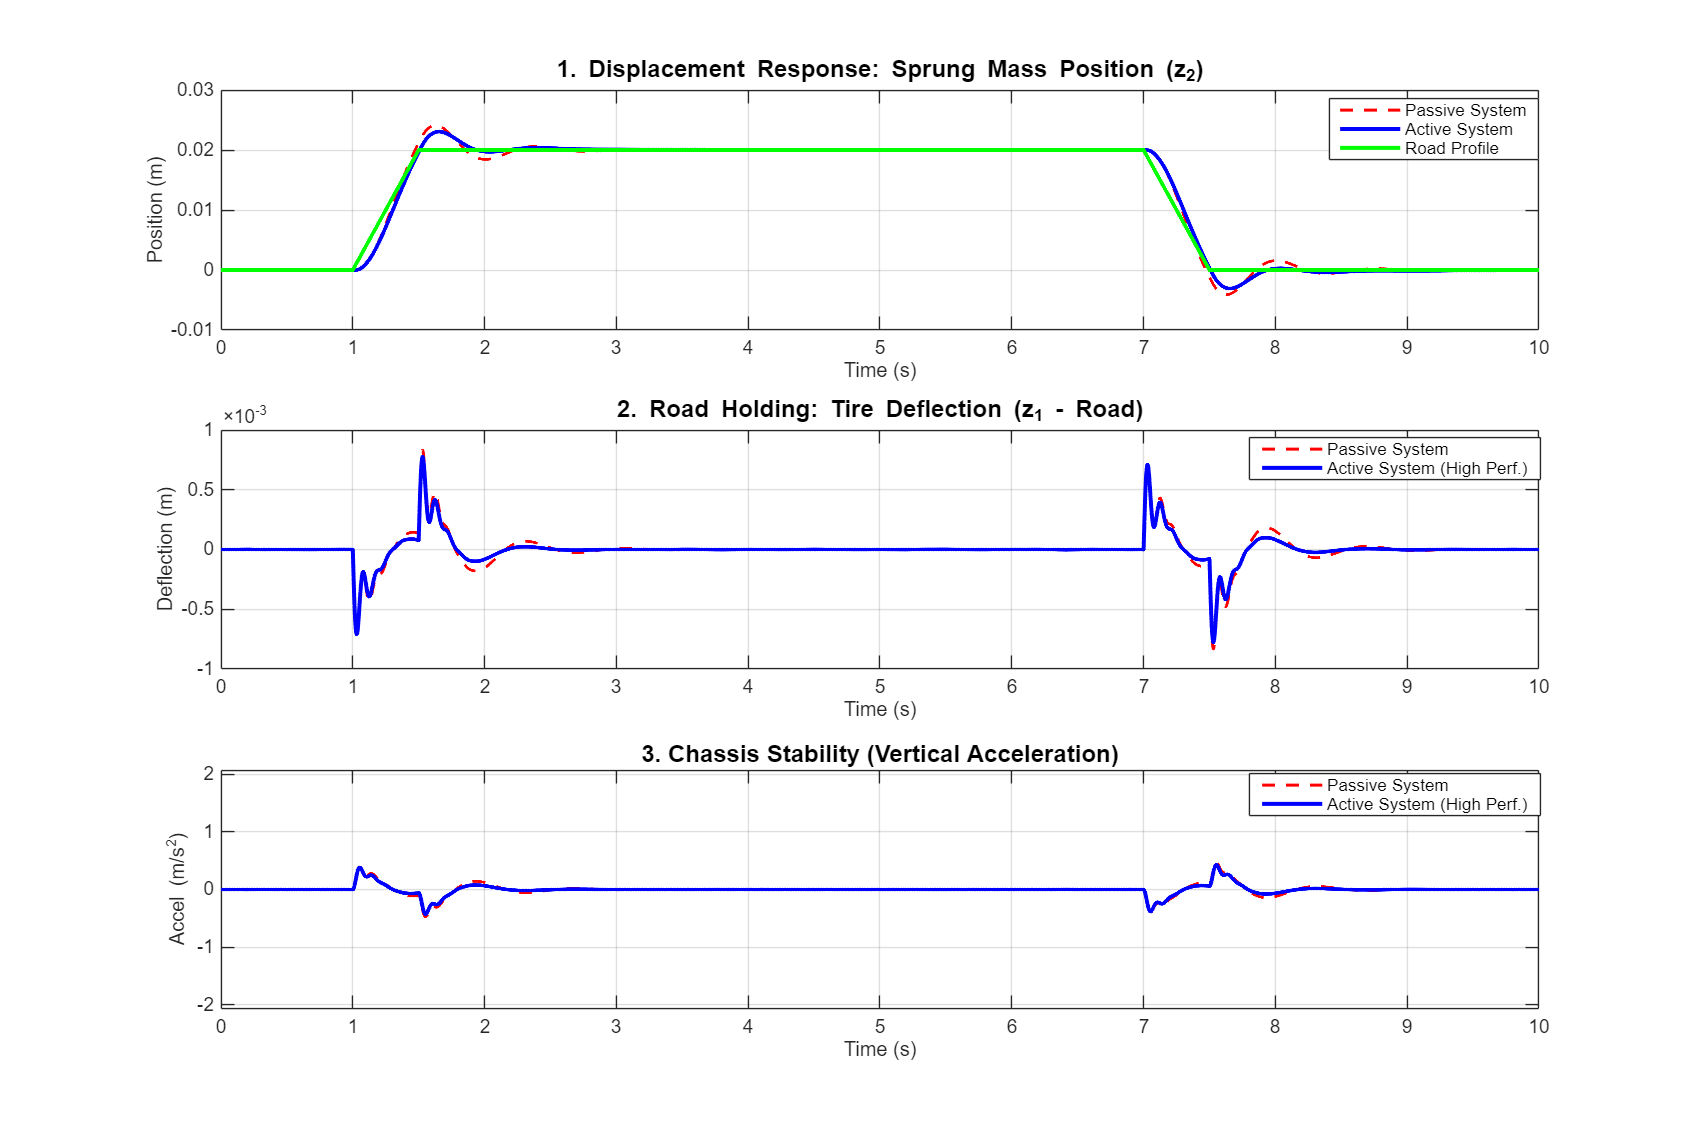


figure('Name', 'Active Suspension Performance Analysis','Color', 'w', 'Position', [100, 100, 1200, 800]);

subplot(3, 1, 3);
plot(out.passive_accel.time, out.passive_accel.signals.values, 'r--', 'LineWidth', 1.5); hold on;
plot(out.active_accel.time, out.active_accel.signals.values, 'b-', 'LineWidth', 2);
title('3. Chassis Stability (Vertical Acceleration)', 'FontSize', 12);
ylabel('Accel (m/s^2)', 'FontSize', 10);
xlabel('Time (s)', 'FontSize', 10);
legend('Passive System', 'Active System (High Perf.)', 'Location', 'Best');
grid on;

subplot(3, 1, 2);
plot(out.passive_deflect.time, out.passive_deflect.signals.values, 'r--', 'LineWidth', 1.5); hold on;
plot(out.active_deflect.time, out.active_deflect.signals.values, 'b-', 'LineWidth', 2);
title('2. Road Holding: Tire Deflection (z_1 - Road)', 'FontSize', 12);
ylabel('Deflection (m)', 'FontSize', 10);
xlabel('Time (s)', 'FontSize', 10);
legend('Passive System', 'Active System (High Perf.)', 'Location', 'Best');
grid on;

subplot(3, 1, 1);
plot(out.passive_pos.time, out.passive_pos.signals.values, 'r--', 'LineWidth', 1.5); hold on;
plot(out.active_pos.time, out.active_pos.signals.values, 'b-', 'LineWidth', 2);
plot(out.reference.time, out.reference.signals.values, 'g-', 'LineWidth', 2);
title('1. Displacement Response: Sprung Mass Position (z_2)', 'FontSize', 12);
xlabel('Time (s)', 'FontSize', 10);
ylabel('Position (m)', 'FontSize', 10);
legend('Passive System', 'Active System','Road Profile', 'Location', 'SouthEast');
grid on;

subplot(3,1,1)
legend(["Passive System", "Active System", "Road Profile"], "Location", "none", "Position", [0.7848 0.8591 0.1165, 0.0539])
subplot(3,1,2)
legend(["Passive System", "Active System (High Perf.)"], "Position", [0.7391 0.5771 0.1621, 0.0375])
subplot(3,1,3)
xlim([0.00 10.00])
ylim([-2.07 2.07])
legend(["Passive System", "Active System (High Perf.)"], "Position", [0.7391 0.2807 0.1621, 0.0375])

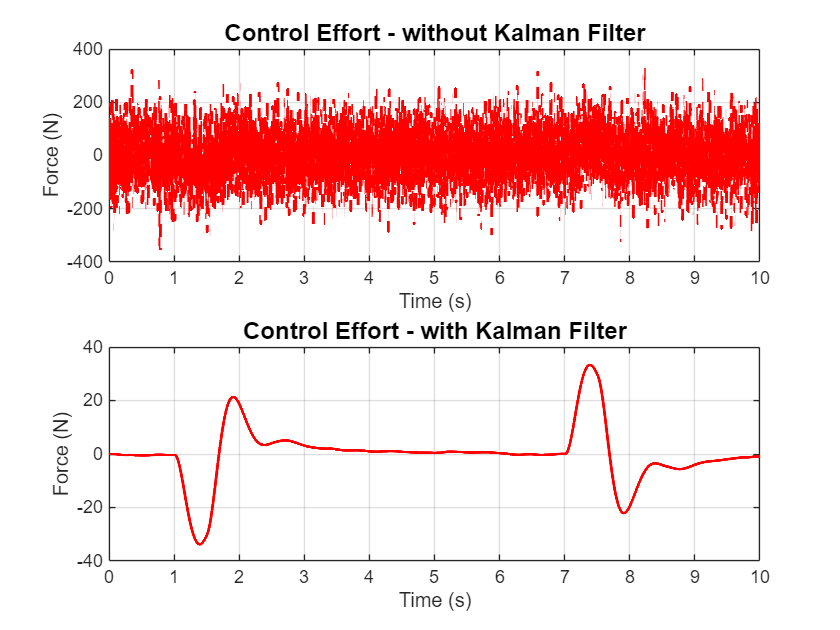

figure
subplot(2,1,1);
plot(out.wo_kal.time, out.wo_kal.signals.values, 'r--', 'LineWidth', 1.5);
title('Control Effort - without Kalman Filter', 'FontSize', 12);
xlabel('Time (s)', 'FontSize', 10);
ylabel('Force (N)', 'FontSize', 10);
grid on;
subplot(2,1,2);
plot(out.w_kal.time, out.w_kal.signals.values, 'r-', 'LineWidth', 1.5);
title('Control Effort - with Kalman Filter', 'FontSize', 12);
xlabel('Time (s)', 'FontSize', 10);
ylabel('Force (N)', 'FontSize', 10);
grid on;